**Parameters**

% M matrix -> it's symmetric
m1 = 96.8;
m2 = -3.57;
m3 = -3.57;
m4 = 0.258;

% C matrix
c1 = 0;
c2 = -50.8;
c3 = 0.436;
c4 = 2.20;

% K0 matrix
k11 = -901.0;
k12 = 35.17;
k13 = 35.17;
k14 = -12.03;

% K2 matrix
k21 = 0;
k22 = -87.06;
k23 = 0;
k24 = 3.50;

V = 6.1;

**State Space representation**

a1 = k11+k21*V^2;
a2 = k12+k22*V^2;
a3 = k13+k23*V^2;
a4 = k14+k24*V^2;

A1 = m2/(m2*m3-m1*m4);
A2 = m4/m2;
A3 = m1/m2;

A = [
    0                                     0                             1                               0;
    0                                     0                             0                               1;
    A1*A2*a1-A1*a3                     A1*A2*a2-A1*a4                 A1*A2*c1*V-A1*c3*V                  A1*A2*c2*V-A1*c4*V;
    -A1*A2*A3*a1+A1*A3*a3-a1/m2     -A1*A2*A3*a2+A1*A3*a4-a2/m2     -A1*A2*A3*c1*V+A1*A3*c3*V-c1*V/m2     -A1*A2*A3*c2*V+A1*A3*c4*V-c2*V/m2;
];

B = [
    0;
    0;
    A1;
    -A3*A1
];

C = [1 0 0 0];
D = 0;

sys_ss = ss(A, B,C,D)

sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3    8.741    33.09  -0.7764     2.62
   x4   -15.36   -0.227   -21.05   -15.76
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.2919
   x4   7.915
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



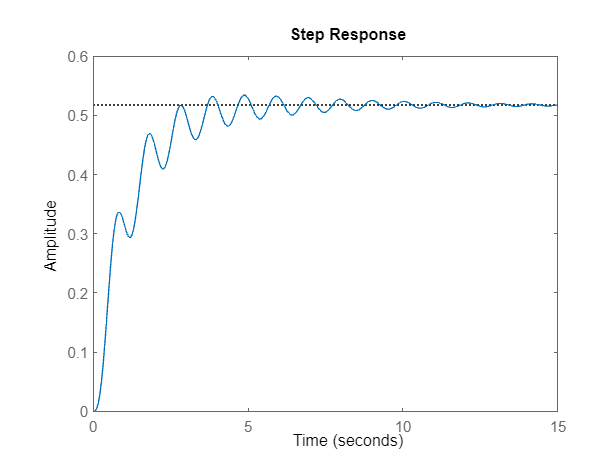

step(sys_ss)

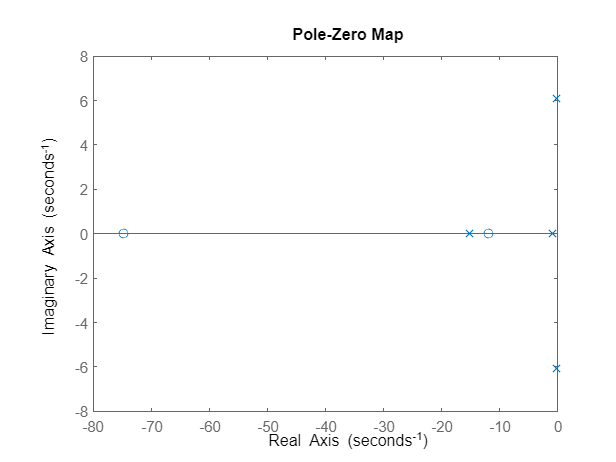

pzmap(sys_ss)

eig(A)

ans =   -0.9063 + 0.0000i
  -0.2564 + 6.0736i
  -0.2564 - 6.0736i
 -15.1212 + 0.0000i


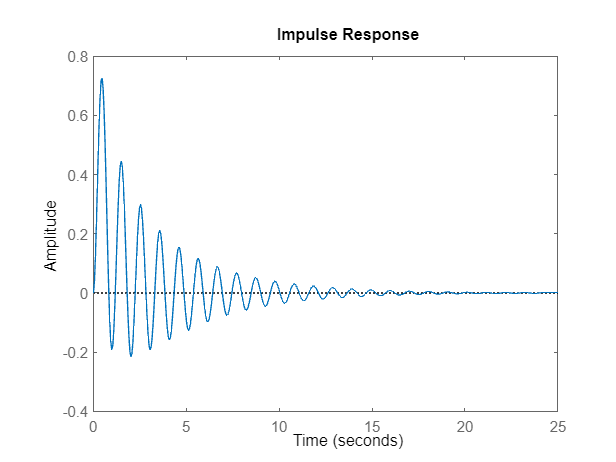

impulse(sys_ss)

**transfer function**

[tf_num, tf_denum] = ss2tf(A,B,C,D)

tf_num =          0         0    0.2919   25.3387  262.0166


tf_denum =     1.0000   16.5403   58.8767  599.3133  506.4535


sys_tf = tf(tf_num, tf_denum)

sys_tf =
 
           0.2919 s^2 + 25.34 s + 262
  ---------------------------------------------
  s^4 + 16.54 s^3 + 58.88 s^2 + 599.3 s + 506.5
 
Continuous-time transfer function.



pole(sys_tf)

ans =  -15.1212 + 0.0000i
  -0.2564 + 6.0736i
  -0.2564 - 6.0736i
  -0.9063 + 0.0000i


**Lyapunov method for stability analysis**

Q = eye(length(A))

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


P = lyap(A,Q)

P =     2.2573   -1.3340   -0.5000   -3.9028
   -1.3340    1.6218    3.9028   -0.5000
   -0.5000    3.9028   34.2541  -37.6717
   -3.9028   -0.5000  -37.6717   54.1503


eig(P)

ans =     0.0320
    0.5826
    8.3165
   83.3524



if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is stable.


**CCF form from transfer function**

A_ccf = [
    0                  1               0               0;
    0                  0               1               0;
    0                  0               0               1;
    -tf_denum(5)    -tf_denum(4)    -tf_denum(3)    -tf_denum(2)
];
B_ccf = [
    0;
    0;
    0;
    1
];

C_ccf = [tf_num(5)  tf_num(4)   tf_num(3)   tf_num(2)];

D_ccf = 0;

sys_ss_ccf = ss(A_ccf,B_ccf,C_ccf,D_ccf)

sys_ss_ccf =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0       1       0
   x3       0       0       0       1
   x4  -506.5  -599.3  -58.88  -16.54
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
           x1      x2      x3      x4
   y1     262   25.34  0.2919       0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



if rank(ctrb(sys_ss_ccf.A, sys_ss_ccf.B)) == length(A_ccf)
    disp('CCF form is correct.')
else
    disp('CCF form is not correct.')
end

CCF form is correct.


if rank(obsv(sys_ss_ccf.A, sys_ss_ccf.C)) == length(A_ccf)
    disp('CCF form is observable too.')
else
    disp('CCF form is not observable.')
end

CCF form is observable too.


step(sys_ss_ccf)